Problema do cilindro escavado

sólido cujos limites são:

plano horizontal z=0

uma superfície cilíndrica de raio r = 1 e altura h =1

e uma superfície cónica de raio (máximo) r = 1 e altura h = 1

Cálculos

% volume do sólido em coordenadas cartesianas
syms x y z
I1 = int(1,z,0,sqrt(x^2+y^2))

$$I1 = \sqrt{x^{2}+y^{2}}$$

I2 = int(I1,y,-sqrt(1-x^2),sqrt(1-x^2))

$$I2 = \int_{-\sqrt{1-x^{2}}}^{\sqrt{1-x^{2}}}\sqrt{x^{2}+y^{2}}\mathrm{d}y$$

I3 = int(I2,x,-1,1)

$$I3 = \int_{-1}^{1}\int_{-\sqrt{1-x^{2}}}^{\sqrt{1-x^{2}}}\sqrt{x^{2}+y^{2}}\mathrm{d}y\mathrm{d}x$$


% volume do sólido em coordenadas cilíndricas
syms rho theta z
I1 = int(rho,z,0,rho)

$$I1 = \rho^{2}$$

I2 = int(I1,theta,0,2*pi)

$$I2 = 2\,\pi \,\rho^{2}$$

I3 = int(I2,rho,0,1)

$$I3 = \frac{2\,\pi }{3}$$

Representação gráfica

superfície cilíndrica

n = 50

n = 50

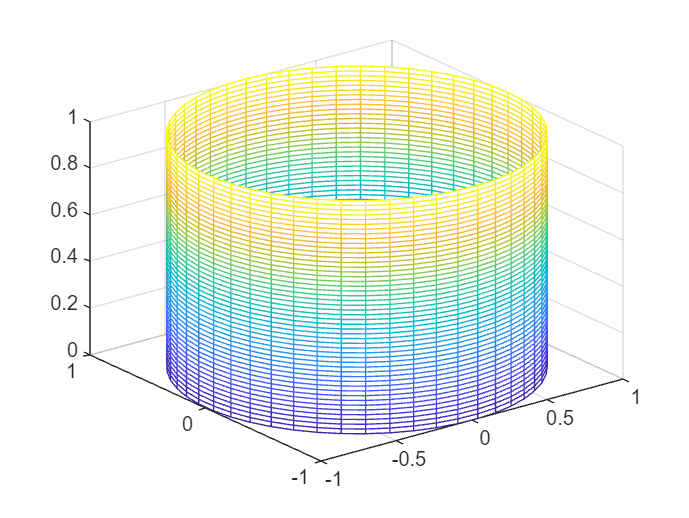


% passo01: grelha de pontos das variáveis independentes
theta = linspace(0,2*pi,n);
z = linspace(0,1,n);
[theta,z] = meshgrid(theta,z);

% passo02: declarar e definir a variável dependente
rho = 1;

% passo03: transformar as coordenadas cilíndricas
% em coordenadas cartesianas
[xCilindro,yCilindro,zCilindro] = pol2cart(theta,rho,z);

% passo04: esboçar a superfície
mesh(xCilindro,yCilindro,zCilindro)

superfície cónica

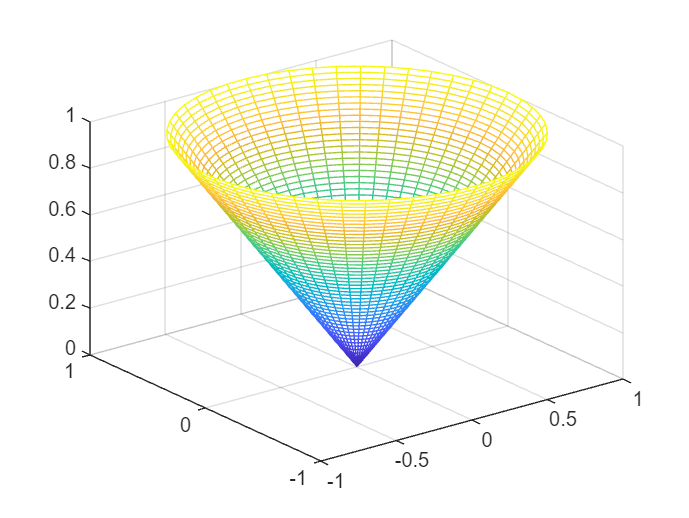

% passo01: grelha de pontos das variáveis independentes
theta = linspace(0,2*pi,n);
rho = linspace(0,1,n);
[theta,rho] = meshgrid(theta,rho);

% passo02: declarar e definir a variável dependente
z = rho;

% passo03: transformar as coordenadas cilíndricas
% em coordenadas cartesianas
[xCone,yCone,zCone] = pol2cart(theta,rho,z);

% passo04: esboçar a superfície
mesh(xCone,yCone,zCone)

juntando as superfícies

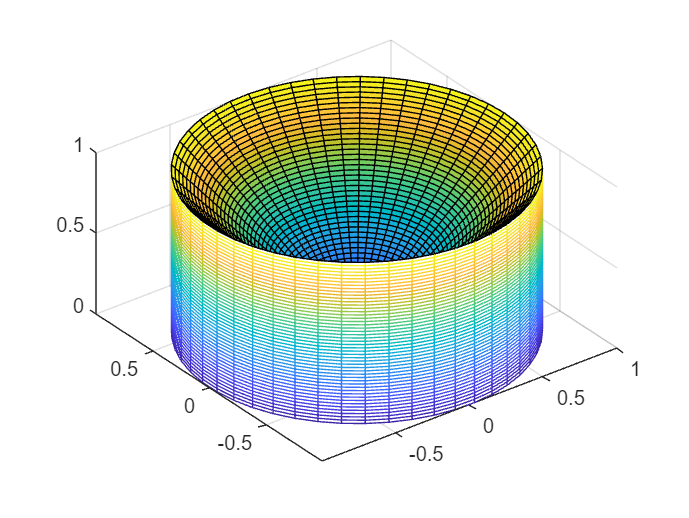

mesh(xCilindro,yCilindro,zCilindro)
hold("on")
surf(xCone,yCone,zCone)
hold("off")
axis("equal")

chapa circular

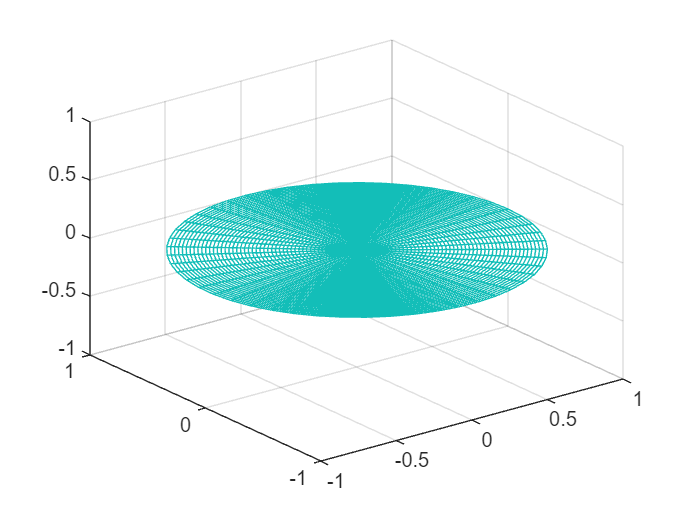

% passo01: grelha de pontos das variáveis independentes
theta = linspace(0,2*pi,n);
rho = linspace(0,1,n);
[theta,rho] = meshgrid(theta,rho);

% passo02: declarar e definir a variável dependente
z = zeros(50,50);

% passo03: transformar as coordenadas cilíndricas
% em coordenadas cartesianas
[xChapa,yChapa,zChapa] = pol2cart(theta,rho,z);

% passo04: esboçar a superfície
mesh(xChapa,yChapa,zChapa)

juntando todas as superfícies

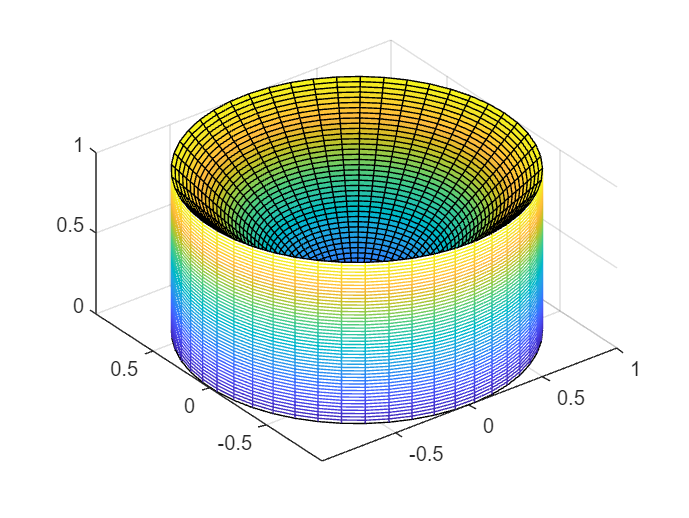

mesh(xCilindro,yCilindro,zCilindro)
hold("on")
surf(xCone,yCone,zCone)
surf(xChapa,yChapa,zChapa)
hold("off")
axis("equal")